clear all
L1=4; L2=3; L3=2;
P1=[0 0 0]'; PC1=[L1/2 0 0]';
P2=[L1 0 0]';PC2=[L2/2 0 0]';
P3=[L2 0 0]';PC3=[L3/2 0 0]';
m1=20; m2=15; m3=10;
I1=[0 0 0;
    0 0 0;
    0 0 0.5];
I2=[0 0 0;
    0 0 0;
    0 0 0.2];
I3=[0 0 0;
    0 0 0;
    0 0 0.1];
theta1=pi/18;    theta2=pi/9;   theta3=pi/6;
theta1_dot=1;    theta2_dot=2;  theta3_dot=3;
theta1_dot2=0.5; theta2_dot2=1; theta3_dot2=1.5;
R10=[cos(theta1) sin(theta1) 0;
    -sin(theta1) cos(theta1) 0;
     0           0           1];
R21=[cos(theta2) sin(theta2) 0;
    -sin(theta2) cos(theta2) 0;
     0           0           1];
R32=[cos(theta3) sin(theta3) 0;
    -sin(theta3) cos(theta3) 0;
     0           0           1];
R23=[cos(theta3) -sin(theta3) 0;
     sin(theta3)  cos(theta3) 0;
      0           0           1];
R12=[cos(theta2) -sin(theta2) 0;
     sin(theta2)  cos(theta2) 0;
      0           0           1];
g=9.81;
v0_dot=[0 g 0]'; % consider gravity

omega1=[0 0 theta1_dot]';
omega1_dot=[0 0 theta1_dot2]'; % precondition is {0} is set conventionally
v1_dot=R10*v0_dot;
vC1_dot=cross(omega1_dot,PC1)+cross(omega1,cross(omega1,PC1))+v1_dot;
F1=m1*vC1_dot;
N1=I1*omega1_dot+cross(omega1,I1*omega1);
%-----------------------------------------
omega2=R21*omega1+[0 0 theta2_dot]';
omega2_dot=R21*omega1_dot+cross(R21*omega1,[0 0 theta2_dot]')+[0 0 theta2_dot2]';
v2_dot=R21*(cross(omega1_dot,P2)+cross(omega1,cross(omega1,P2))+v1_dot);
vC2_dot=cross(omega2_dot,PC2)+cross(omega2,cross(omega2,PC2))+v2_dot;
F2=m2*vC2_dot;
N2=I2*omega2_dot+cross(omega2,I2*omega2);
%---------------------------------------------
omega3=R32*omega2+[0 0 theta3_dot]'; % checked
omega3_dot=R32*omega2_dot+cross(R32*omega2,[0 0 theta3_dot]')+[0 0 theta3_dot2]'; %checked
v3_dot=R32*(cross(omega2_dot,P3)+cross(omega2,cross(omega2,P3))+v2_dot);
vC3_dot=cross(omega3_dot,PC3)+cross(omega3,cross(omega3,PC3))+v3_dot; % has been checked. equal to my analytical results
% vC3_dot=
% [-L1*theta1_dot^2*cos(theta2+theta3)+L1*theta1_dot2*sin(theta2+theta3)+g*sin(theta1+theta2+theta3)-L2*(theta1_dot+theta2_dot)^2*cos(theta3)+L2*(theta1_dot2+theta2_dot2)*sin(theta3)-L3/2*(theta1_dot+theta2_dot+theta3_dot)^2;
%   L1*theta1_dot^2*sin(theta2+theta3)+L1*theta1_dot2*cos(theta2+theta3)+g*cos(theta1+theta2+theta3)+L2*(theta1_dot+theta2_dot)^2*sin(theta3)+L2*(theta1_dot2+theta2_dot2)*cos(theta3)+L3/2*(theta1_dot2+theta2_dot2+theta3_dot2);
% 0]
F3=m3*vC3_dot;
N3=I3*omega3_dot+cross(omega3,I3*omega3);

f3=F3; % precondition: No external force applied on the end.
n3=N3+cross(PC3,F3);
tau3=n3'*[0 0 1]';
f2=R23*f3+F2;
n2=N2+R23*n3+cross(PC2,F2)+cross(P3,R23*f3);
tau2=n2'*[0 0 1]';
f1=R12*f2+F1;
n1=N1+R12*n2+cross(PC1,F1)+cross(P2,R12*f2);
tau1=n1'*[0 0 1]';
tau=[tau1 tau2 tau3]'

tau =   853.6032
  637.2026
  296.8187


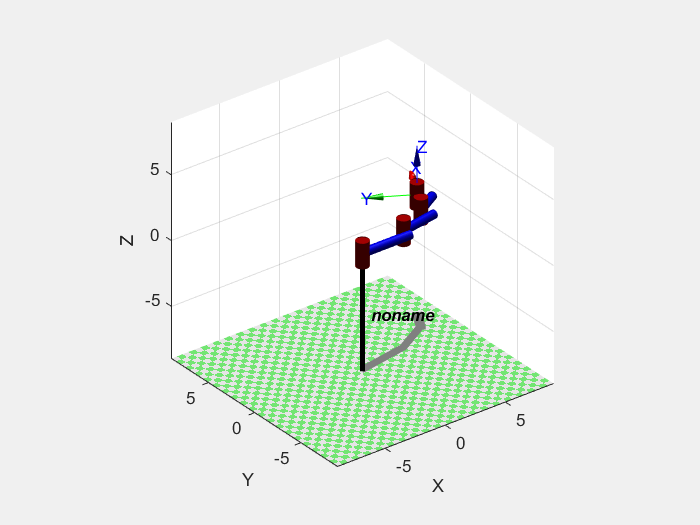

% check by using Corke MATLAB Robotics Toolbox
% standard DH
link1=Link('d',0,'a',4,'alpha',0,'m',20,'r',-PC1,'I',I1); % here I use standard DH, thus -PC1
link2=Link('d',0,'a',3,'alpha',0,'m',15,'r',-PC2,'I',I2);
link3=Link('d',0,'a',2,'alpha',0,'m',10,'r',-PC3,'I',I3); 
manipulator=link1+link2+link3;
manipulator.plot([theta1 theta2 theta3]);

tau_check1=manipulator.rne([theta1 theta2 theta3],[theta1_dot theta2_dot theta3_dot],[theta1_dot2 theta2_dot2 theta3_dot2],[0 g 0])

tau_check1 =   853.6032  637.2026  296.8187


gravityload=manipulator.gravload([theta1 theta2 theta3],[0 g 0])

gravityload =    1.0e+03 *

    1.8476    0.4951    0.0491


% modified DH
clear all; close
L1=4; L2=3; L3=2;
PC1=[L1/2 0 0]';
PC2=[L2/2 0 0]';
PC3=[L3/2 0 0]';
link0=Link('d',0,'a',0,'alpha',0,'modified','m',20,'r',PC1,'I',[0 0 0.5]');  % a0=0, alpha0=0, d1=0, theta1
link1=Link('d',0,'a',4,'alpha',0,'modified','m',15,'r',PC2,'I',[0 0 0.5]');  % a1=4, alpha1=0, d2=0, theta2
link2=Link('d',0,'a',3,'alpha',0,'modified','m',10,'r',PC3,'I',[0 0 0.2]'); % a2=3, alpha2=0, d3=0, theta3
link3=Link('d',0,'a',2,'alpha',0,'modified');  % a3=2, alpha3=0, d4=0, theta_H=0
manipulator=link0+link1+link2+link3

 
manipulator = 
 
noname:: 4 axis, RRRR, modDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          0|          4|          0|          0|
|  3|         q3|          0|          3|          0|          0|
|  4|         q4|          0|          2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


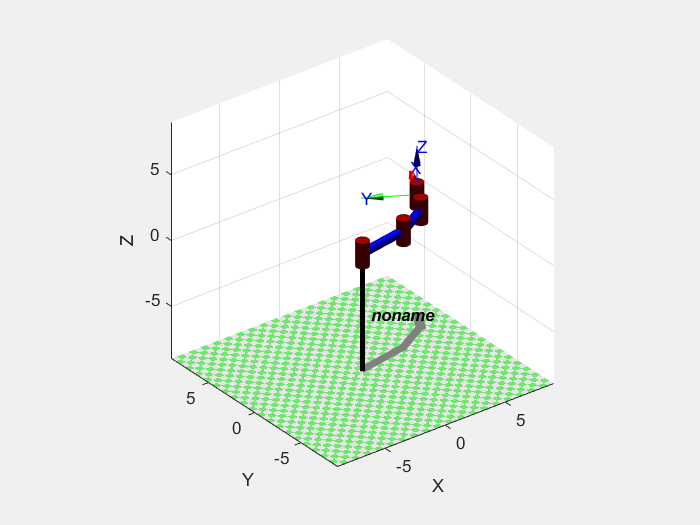

manipulator.plot([pi/18 pi/9 pi/6 0])

tau_check2=manipulator.rne([pi/18 pi/9 pi/6 0],[1 2 3 0],[0.5 1 1.5 0],[0 9.81 0])

tau_check2 =   854.3532  637.9526  297.1187         0


gravityload=manipulator.gravload([pi/18 pi/9 pi/6 0],[0 9.81 0])

gravityload =    1.0e+03 *

    1.8476    0.4951    0.0491         0
